## Stat exam prep & general help

- notes

clc; clear;

% data = xlsread("Data_M4STI1_2017E.xlsx", 'K:L');
data = readtable("Data_M4STI1_2017E.xlsx")


opg3_brembo = rmmissing(table2array(data(:,"Opg3_Brembo")));
opg3_cl = rmmissing(table2array(data(:, "Opg3_CI")));

deskripts(opg3_brembo',"Brembo")
deskripts(opg3_cl',"Brembo")


## Visuals

rng(2)
randmat = [2.2:0.1:3.5, 3.6, 4.2:0.1:5.2];

stemleafplot(randmat, -1)

figure
histogram(randmat, 2:1:6);

title("Histo")


### Histo med categorical

figure

cat = categorical(floor(randmat), [2, 3, 4, 5], ["Starts with 2","Starts with 3","Starts with 4","Starts with 5"]);

histogram(cat)
ylim([0,10])


## Boxplots

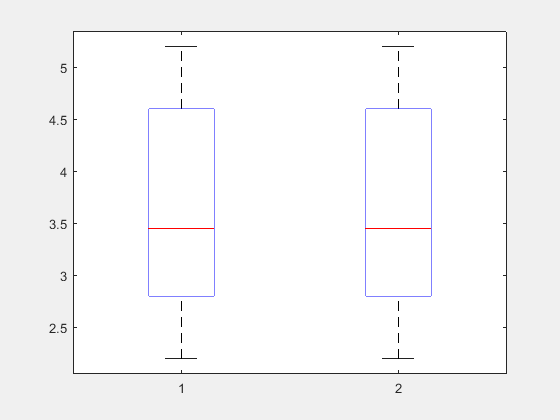

figure("Visible","on")
boxplot([randmat',randmat'])

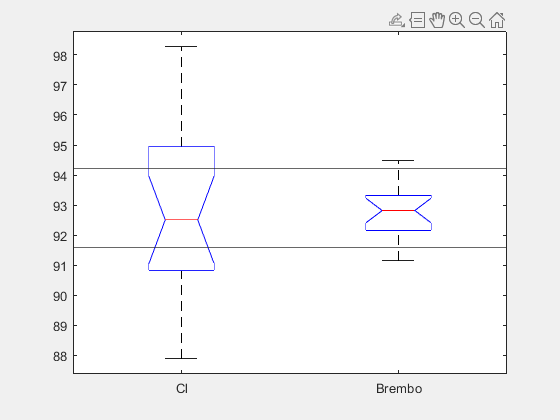


% Brembo og Cl
figure("Visible","on")
boxplot([opg3_cl, opg3_brembo],["Cl","Brembo"],"Notch","on")
hold on
yline(h(1))
yline(h(2))
hold off

% normrnd data
n1 = normrnd(5,1,100,1);
n2 = normrnd(6,1,100,1);

[d,g,h,j]=ztest(n1, 5,1,"Alpha",0.05);

figure
boxplot([n1,n2], ["Jeff","John"],"Notch","on")

hold on
yline(h(1))
yline(h(2))
hold off



d = 0

g = 0.4972

h =     4.8719
    5.2639


j = 0.6790


ttest2popMiddelInd_Test4(opg3_brembo, opg3_cl, "left",95, 0)


